% 1 - Bone W:2000 L:500
% 2 - Lung W:1600 L:-600
% 3 - Abdomen W:400 L:50
% 4 - Brain W:700 L:30
% 5 - Soft tissue W:350 L:50
% 6- Liver W:160 L:50

windows = [
    [2000 500]; 
    [1600 -600];
    [400 50];
    [700 30];
    [350 50];
    [160 50];
   ];


vol = dicomreadVolume(".\1");
vol = squeeze(vol);


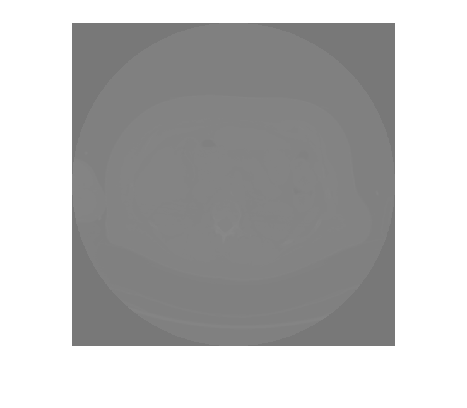

s = size(vol);
slice = vol(:,:,50);
imshow(slice);



wl = 300

wl = 300

ww = 2000

ww = 2000


p = slice;

L = wl - ww/2

L = -700

H = wl + ww/2

H = 1300

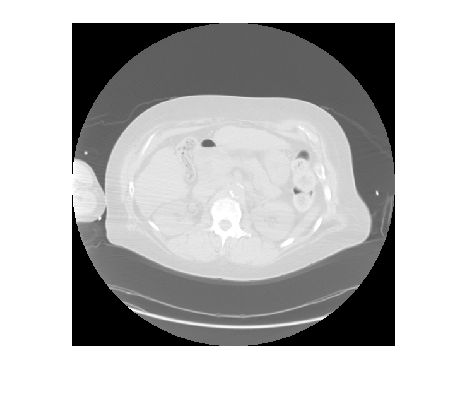


for i=1:512
    for j=1:512
        c = slice(i,j);
        if (c<L) 
            p(i,j) = 0 ;
        elseif (c>H)
            p(i,j) = 255;
        else
            p(i,j) = uint8((double((c - L))/double(H-L))*255);
        end
        
    end
end

p = uint8(p);
imshow(p);


% % convert slice stack into column vectors, one colume per slice
% tic
% c = reshape(vol, s(1)*s(2), s(3));
% toc
% 
% % apply window function
% w = windows(3);
% 
% 
% % convert back to slice stacks
% tic
% v = reshape(c, [s(1) s(2) s(3)]);
% toc 
% 
% tic
% ww = 2000;
% wl = -200;
% h = wl + ww/2;
% l = wl - ww/2;
% s = size(vol);
% 
% for i=1:s(1)
%     for j=1:s(2)
%         for k=1:s(3)
%             if (vol(i,j,k))<l 
%                 g(i,j,k) = 0;
%             elseif (vol(i,j,k)>h)
%                 g(i,j,k) = 255;
%             else
%                 g(i,j,k) = ((vol(i,j,k)-l)/(ww))*255;
%             end
%         end
%     end
% end
% 
% toc
% g = uint8(g);
% sliceViewer(g);